# Introduction to Robotics Lab 8

Syed Mustafa

## Task 1

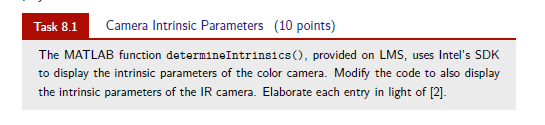

determineIntrinsics(0);


color_intrinsics = struct with fields:
     width: 1920
    height: 1080
       ppx: 931.9031
       ppy: 525.8997
        fx: 1.4071e+03
        fy: 1.4071e+03
     model: 0
    coeffs: [0 0 0 0 0]


depth_intrinsics = struct with fields:
     width: 640
    height: 480
       ppx: 316.3301
       ppy: 245.5135
        fx: 475.2710
        fy: 475.2711
     model: 2
    coeffs: [0.1297 0.1540 0.0047 0.0061 -0.0812]


ans = struct with fields:
     width: 1920
    height: 1080
       ppx: 931.9031
       ppy: 525.8997
        fx: 1.4071e+03
        fy: 1.4071e+03
     model: 0
    coeffs: [0 0 0 0 0]


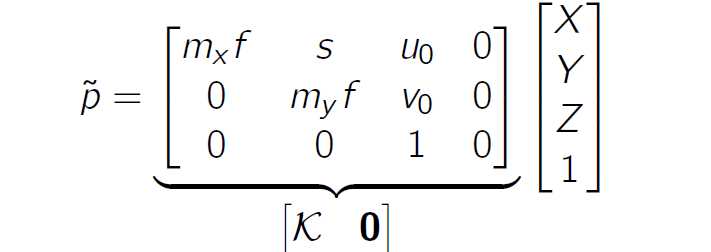

Such that:

- 
$$f_x = m_xf \\ f_y = m_yf
$$


- 
$$ppx = u_0\\ppy = v_0$$


- Width  =  number of rows in the image, i.e. Let ***R*** be the set of all row vectors in image ***M*** then:    $|R| = width$ 

- Height =  number of columns in the image, i.e. Let ***C*** be the set of all row vectors in image ***M*** then: $|C| = width$

## Task 2

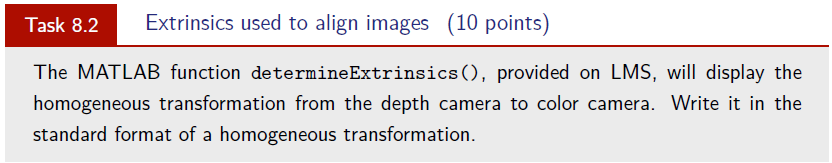

T = determineExtrinsics()

Tdc = struct with fields:
       rotation: [1.0000 -0.0016 -4.0173e-04 0.0016 1.0000 -0.0031 4.0682e-04 0.0031 1.0000]
    translation: [0.0247 0.0013 0.0043]


T =     1.0000   -0.0016   -0.0004    0.0247
    0.0016    1.0000   -0.0031    0.0013
    0.0004    0.0031    1.0000    0.0043
         0         0         0    1.0000


T =     1.0000   -0.0016   -0.0004    0.0247
    0.0016    1.0000   -0.0031    0.0013
    0.0004    0.0031    1.0000    0.0043
         0         0         0    1.0000


## Task 3

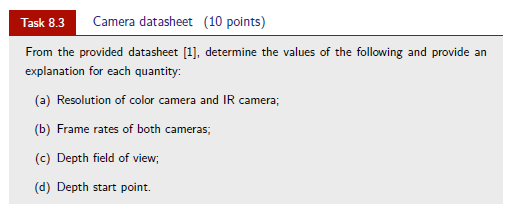

**ANSWER**

**Resolution: **640x480 (IR) 1920x1080 (Depth)

**Frame Rates(FPS): **30,60,120,200 (IR) 10,30,60 (Depth)

**Depth field of view:** Horizontal FOV$\degree
$: 69±3 Vertical FOV$\degree$: 54±2

**Depth Start Point: **Front of Lens(Z’): 0.9mm, Back of Module (Z”): 3.0mm

## Task 4 

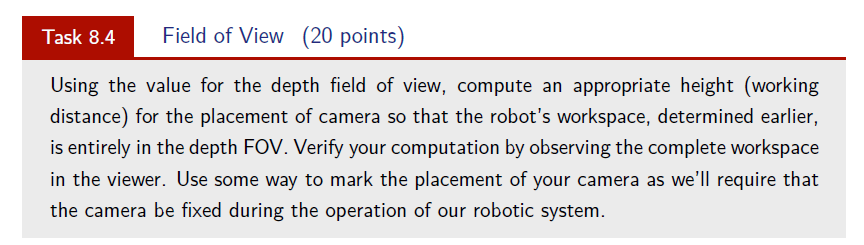

Take working from sull

Take pic of real sense

## Task 5

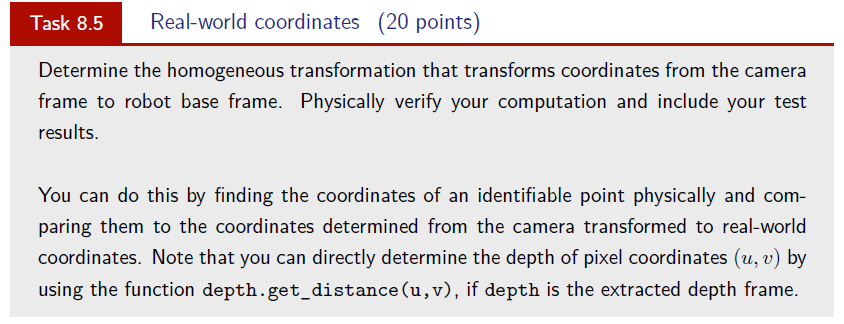

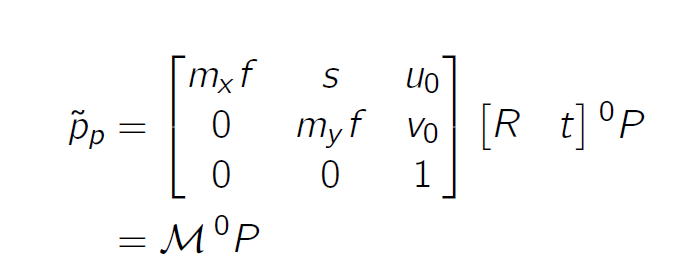

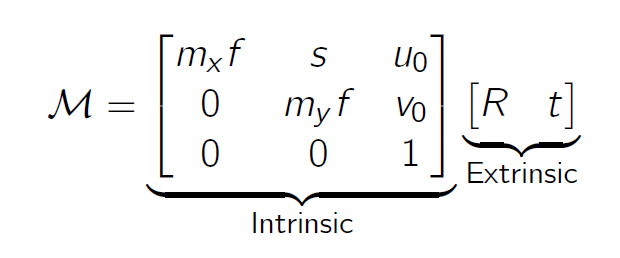

The frame **{C}** was:

(Insert the picture here)

So *R *will be a rotation matrix $R  = R_{z,\pi}R_{x,whatever} \ni  R_{z,\pi},R_{x,whatever} \in SO(3)$


$$t = (0, 0, zvalue in 8.4 )$$


% % Create a extrinsic [R t] using the specifications above
% Extrinsic = [] 
% K = get_intrinsic(0) %getting K for colour
% 
% % Defining the projection matrix
% M = K * Extrinsic
% 
% % Check the projection matrix, make inverse equations

 % Now use the code in lab to get pixel coordinates
 Pixel_coordinates = []


Pixel_coordinates =

     []



arb = Arbotix('port','COM11', 'nservos',5 );

serPort COM11is in use.   Closing it.


i = 4

### Depth_example 

I have changed the depth example, and made it into a function. Please refer to appendix A for the code

setPosition(arb, [0, pi/2,0 ,0]);pause(2)

The joint angles as expressed in radians are


jointAngles =          0    1.5708         0         0


the modded joint angles are


new_theta =          0    1.5708         0         0


The map theeta is \n


map_theta =    -1.5708         0         0         0   -0.0102


%First we will obtain the value of the index of detection
pixel = colour_object_detection(1)

The width is 640 
   29.9529  213.4706
   29.9286  235.2143
   30.6400  255.8200
   35.5424  386.8935
   49.5000  365.5000
   68.9455  110.5636
  422.2162  136.2973
  523.3697   82.8992
  531.4883  187.8945
  533.2091  354.7291

    10     2

     0     0

   56.8067  312.7689
   59.7653  153.2000
   57.7425  226.5945
   57.1165  357.9806
   64.6358   83.0116
  520.3596  105.1461

     6     2

     0     0

The object is of color Red


pixel =   422.2162  136.2973


u0 = 932; v0 = 526; zc = 69.6;
fx = 1407;
fy = 1407;
%  Now we will change it to the pixel to the pixel coordinates
u = pixel(1) + u0;
v = pixel(2) + v0;




$$u_p = m_xf\frac X Z + u_0$$



$$v_p = m_yf\frac Y Z + v_0$$


Re-writing them gives us:


$$X = \frac {((u-u_o)*Z)} {f_x} \\ 


$$



$$Y = \frac {((v-v_o)*Z)} {f_y} \\ $$


The rotation matrix

$R_{x,\pi}$ = $\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \;\theta  & \sin \;\theta \\
0 & \sin \;\theta  & \cos \;\theta 
\end{array}\right\rbrack$ = $\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & -1 & 0\\
0 & 0 & -1
\end{array}\right\rbrack$

xc = ((u-u0)*zc)/fx

xc = 20.8857

yc = ((v-v0)*zc)/fy

yc = 6.7422


R_T_W = [1 0 0 0;
         0 -1 0 0;
         0 0 -1 zc;
         0 0 0 1];
W_T_R = inv(R_T_W)

W_T_R =     1.0000         0         0         0
         0   -1.0000         0         0
         0         0   -1.0000   69.6000
         0         0         0    1.0000



Xw = W_T_R*[xc;yc;zc;1]

Xw =    20.8857
   -6.7422
         0
    1.0000



setPosition(arb,findOptimalSolution(arb, [Xw(1),Xw(2),0,-pi/2]))

The joint angles as expressed in radians are


jointAngles =    -0.3123    0.0999         0   -1.6707


the modded joint angles are


new_theta =    -0.3123    0.0999         0   -1.6707


The map theeta is \n


map_theta =    -1.8830   -1.4709         0   -1.6707   -0.0102


ans = 0

arb = Arbotix('port','COM11', 'nservos',5);

serPort COM11is in use.   Closing it.


setPosition(arb, [0 0 0 0])
setPosition(findOptimalSolution(arb, [20,0,0,-pi/2]))

## Least square:

rng default
A = sprand(400,300,.5)

A =    (2,1)       0.7307
   (4,1)       0.7944
   (8,1)       0.9237
  (13,1)       0.8167
  (16,1)       0.3942
  (17,1)       0.6558
  (20,1)       0.0229
  (21,1)       0.6015
  (26,1)       0.4700
  (27,1)       0.0502
  (31,1)       0.3609
  (35,1)       0.5093
  (36,1)       0.6078
  (37,1)       0.4769
  (38,1)       0.9408
  (40,1)       0.2216
  (41,1)       0.4068
  (42,1)       0.2090
  (44,1)       0.2566
  (49,1)       0.3332
  (51,1)       0.8957
  (60,1)       0.6833
  (62,1)       0.9438
  (63,1)       0.2589
  (66,1)       0.4040
  (70,1)       0.4930
  (71,1)       0.3343
  (74,1)       0.3930
  (75,1)       0.2568
  (77,1)       0.7191
  (78,1)       0.3715
  (80,1)       0.1616
  (84,1)       0.1092
  (88,1)       0.8513
  (89,1)       0.0496
  (90,1)       0.1634
  (91,1)       0.9527
  (93,1)       0.0785
  (94,1)       0.4871
  (95,1)       0.7188
  (98,1)       0.3939
 (104,1)       0.4644
 (106,1)       0.9479
 (109,1)       0.1017
 (113,1)       0.7709
 (122,

b = rand(400,1);
x = lsqr(A,b)

lsqr stopped at iteration 20 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 0.26.


x =     0.0562
   -0.0724
    0.1310
   -0.0269
    0.0198
    0.0725
    0.0593
   -0.1848
    0.0794
   -0.0482


## Appendix A (Codes)

### Depth Example